# **Fun2Optimize**

Marek Wadinger

#### **Initialize Workspace**

clc; clear all; close all
addpath(genpath('functions'))

#### **Example Problem**

A rectangle is to be inscribed in the ellipse $\frac{x^2}{4}+y^2=1
$. What should be the dimensions of the rectangle to maximize its area? What is the maximum area?

## **1. Formulate the optimization problem**


$${min}\limits_{x,y}~ - 2x*2y \\
s.t. ~~\frac{x^2}{4}+y^2 = 1

$$


Where $x$ is half the width and $y$ is half the height of the rectangle.

**Use elimination method to remove make problem unconstrained**

Derive $y$ from constraint:


$$y = \sqrt{1 - \frac{x^2}{4} \\}
$$


Insert into cost function $J$:


$$J = -4x*\sqrt{1-\frac{x^2}{4}$$


f = @(x) -4*x*sqrt(1-x^2/4)

f = function_handle with value:
    @(x)-4*x*sqrt(1-x^2/4)


df = function_handle with value:
    @(x)(-4+2*x^2)/sqrt(1-x^2/4)


ddf = function_handle with value:
    @(x)(x*(3-1/2*x^2))/(1-x^2/4)^(3/2)


Following condition must be fulfilled $\surd \neq 0$:


$$1-\frac{x^2}{4} \neq 0 \longrightarrow
x \neq\pm 2
$$


## **2. Find the solution of the optimization problem**

Set 'Plot' option to True in any function to see convergence over iterations.

### Set initial parameters

t = 0.2;        % step size
alpha = 0.2;    % how much do we trust the linear extrapolation
beta = 0.5;     % coresponds to crudeness of the search
kmax = 500;     % max number of iterations 
x0 = 1;         % initial point
bounds = [0 2]; % boundaries as whole domain of the function

### **Solve optimization problem**

#### **Gradient Method**

x   = gdm(f, x0, kmax, 't', t, 'Plot', false); x, -f(x)

Optimum reached in:28 iterations... Time:1.6606s


x = 1.4142

ans = 4.0000

#### **Gradient Method Backtracking**

xb  = gdmb(f, x0, kmax, 't', t, 'alpha', alpha, 'beta', beta, ...
          'Plot', false); xb, -f(xb)

Optimum reached in:10 iterations... Time:0.045527s


xb = 1.4142

ans = 4.0000

#### **Newton Method**

xn  = newton(f, x0, kmax, 't', t, 'alpha', alpha, 'beta', beta, ...
            'Plot', false); xn, -f(xn)

Optimum reached in:57 iterations... Time:0.057243s


xn = 1.4142

ans = 4.0000

#### Luus Jaakola

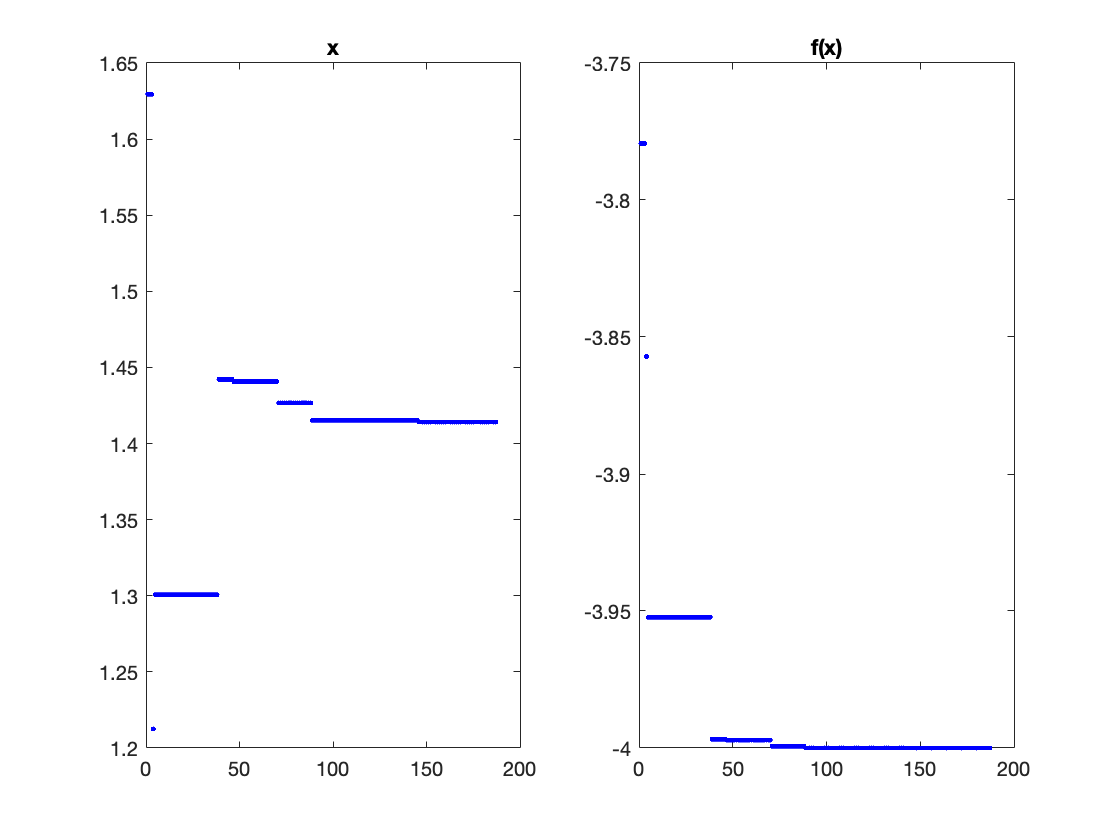

Optimum reached in:188 iterations... Time:3.5773s


xlj = 1.4141

ans = 4.0000

xlj = luusjaakola(f, '', kmax, bounds, 'ShrinkRate', 0.98, ...
                  'Plot', true); xlj, -f(xlj)

#### Simulated annealing

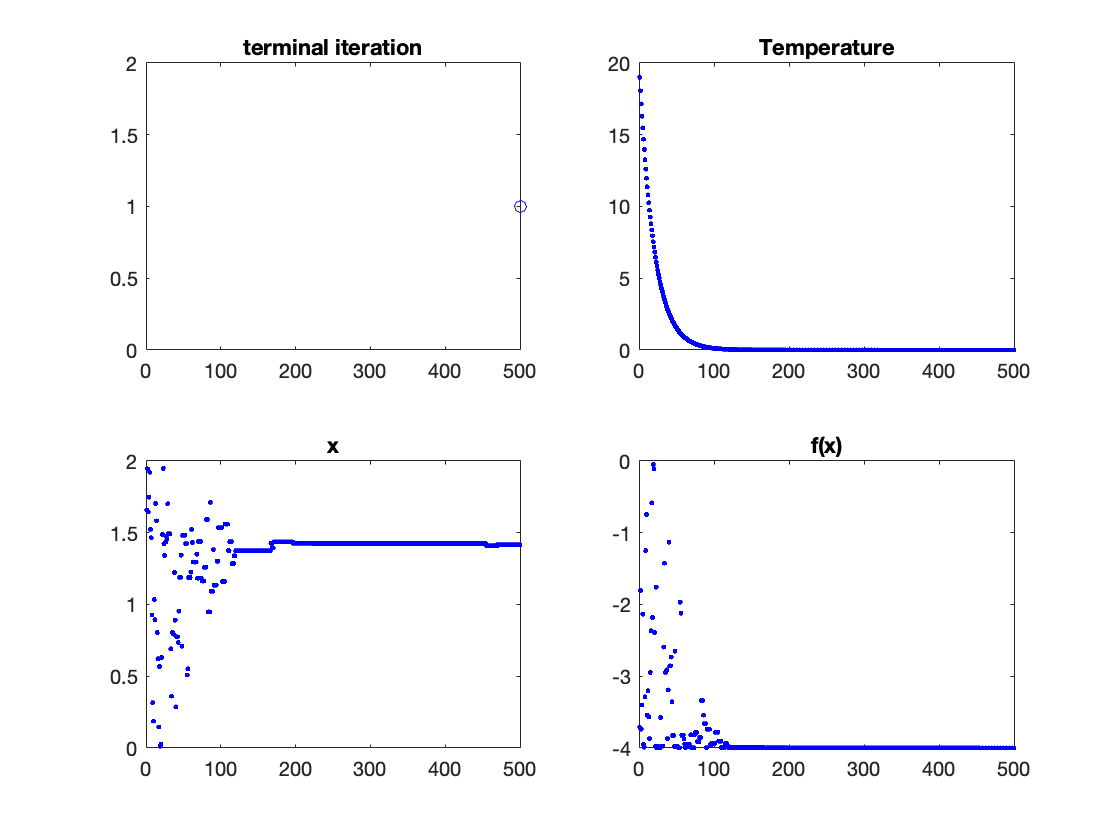

Optimum reached in:500 iterations... Time:22.5712s


xsa = 1.4169

ans = 4.0000

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    0.000000e+00    7.975e-01    3.600e+00
    1       2   -1.773757e+01    4.938e+00    8.860e+00    2.478e+00
    2       7   -8.793340e+00    1.218e+00    3.720e-02    1.104e+00
    3       8   -4.654736e+00    2.349e-01    2.140e+00    5.012e-01
    4       9   -4.177830e+00    4.464e-02    1.034e-01    3.938e-01
    5      10   -4.002193e+00    5.494e-04    2.003e-02    2.836e-02
    6      11   -4.000002e+00    4.576e-07    8.437e-04    7.971e-04
    7      12   -4.000000e+00    1.572e-08    1.377e-05    1.980e-04
    8      13   -4.000000e+00    5.673e-13    2.000e-06    1.183e-06

Feasible point with lower objective function value found.




sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.11.0.1769968 (R2021b)'
       yalmiptime: 1.3797
       solvertime: 0.5556
             info: 'Successfully solved (FMINCON)'
          problem: 0


xy = 1.4142

ans = 4.0000

xsa = simulatedannealing(f, '' , kmax, bounds, ...
                         'Temp', 20, 'T_reduction', 0.95, ...
                         'Plot', true); xsa, -f(xsa)

## 3. Plot solutions

Ellipse

clf(figure(1)); figure(1)
x_center = 0; y_center = 0;
fimplicit(@(x,y) (x-x_center).^2/4 ...
               + (y-y_center).^2 - 1, [-2,2]); hold on

Rectangle

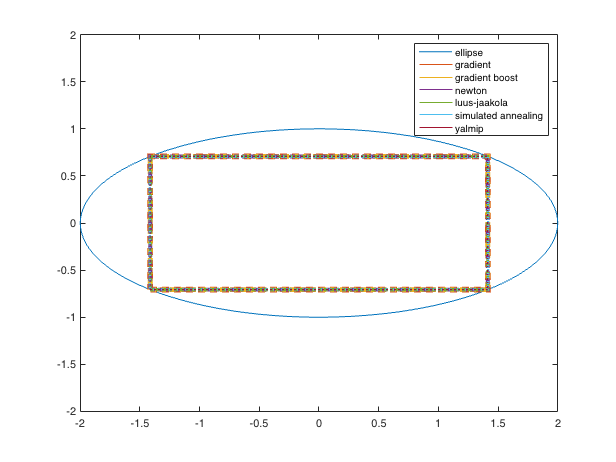

cmp = colororder;
l_x_opts = [x, xb, xn, xlj, xsa, xy];
for i = 1:length(l_x_opts)
    left = l_x_opts(i);
    bottom = sqrt(1-l_x_opts(i)^2/4);

    rectangle('Position',[x_center - left, ...
                      y_center - bottom, ...
                      left*2, ...
                      bottom*2], ...
                      'EdgeColor',cmp(i+1,:)', ...
                      'LineStyle',':', ...
                      'LineWidth',length(l_x_opts)-0.8*i);
    line(nan,nan,'Color',cmp(i+1,:))
end
hold off
legend('ellipse', ...
       'gradient', ...
       'gradient boost', ...
       'newton', ...
       'luus-jaakola', ...
       'simulated annealing', ...
       'yalmip')

## **4. Play with tunning parameters**

Choose optimization method and parameter from dropdown. Define range of values for which you would like to explore metrics (value of argument in optimum, value of cost function, time of optimization and number of iterations).	

opt_method_fcn = function_handle with value:
    @simulatedannealing


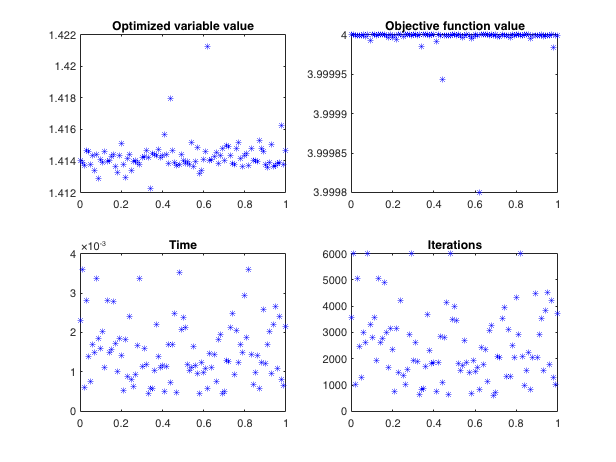

Temperature has influence over ability of an algorithm toaccept worse optimized parameter value in order to escape local minima. The influence is direct - higher temperature increases probability of worse solution being accepted. It has a tendency to increase number of iterations in a complicated way.


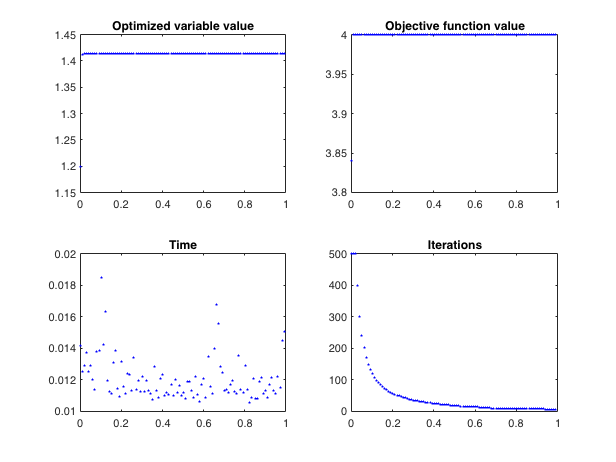

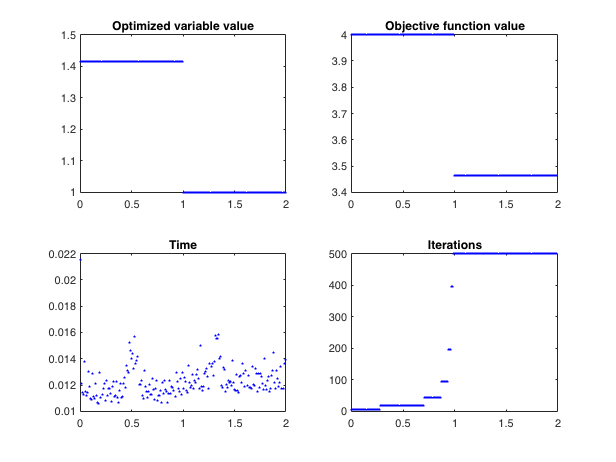

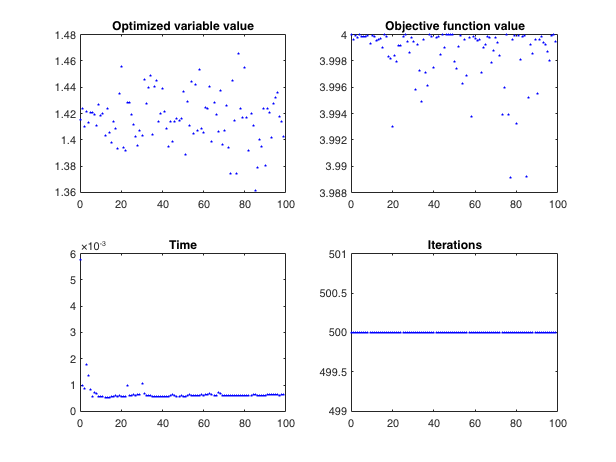

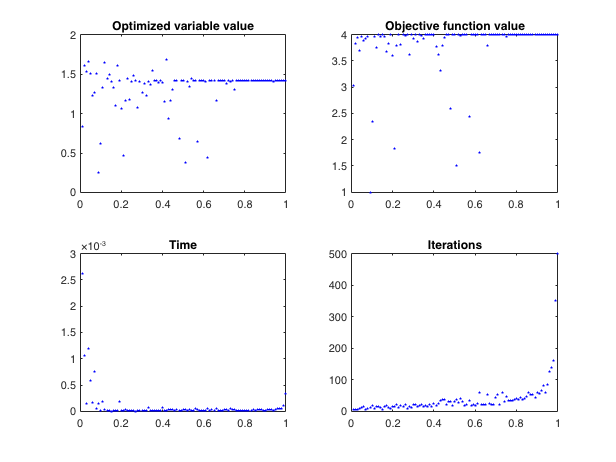

opt_method = "simulatedannealing";
opt_param  = "Temp";
opt_values = 0:0.01:1;
 
optMethodDemo(f, x0, 6000, bounds, opt_method, opt_param, opt_values);